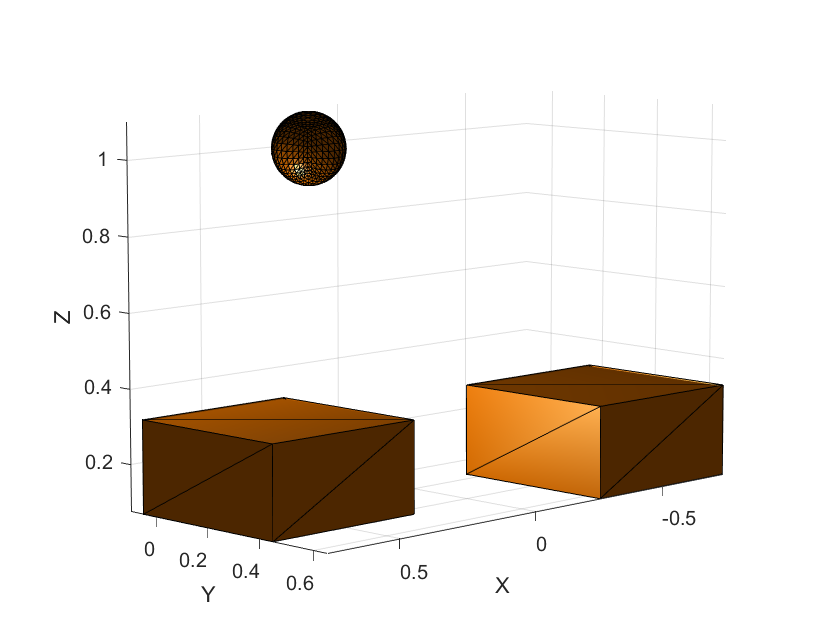

% Create two platforms
platform1 = collisionBox(0.5,0.5,0.25);
platform1.Pose = trvec2tform([-0.5 0.4 0.2]);

platform2 = collisionBox(0.5,0.5,0.25);
platform2.Pose = trvec2tform([0.5 0.2 0.2]);

% Add a light fixture, modeled as a sphere
lightFixture = collisionSphere(0.1);
lightFixture.Pose = trvec2tform([.2 0 1]);

% Store in a cell array for collision-checking
worldCollisionArray = {platform1 platform2 lightFixture};
exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

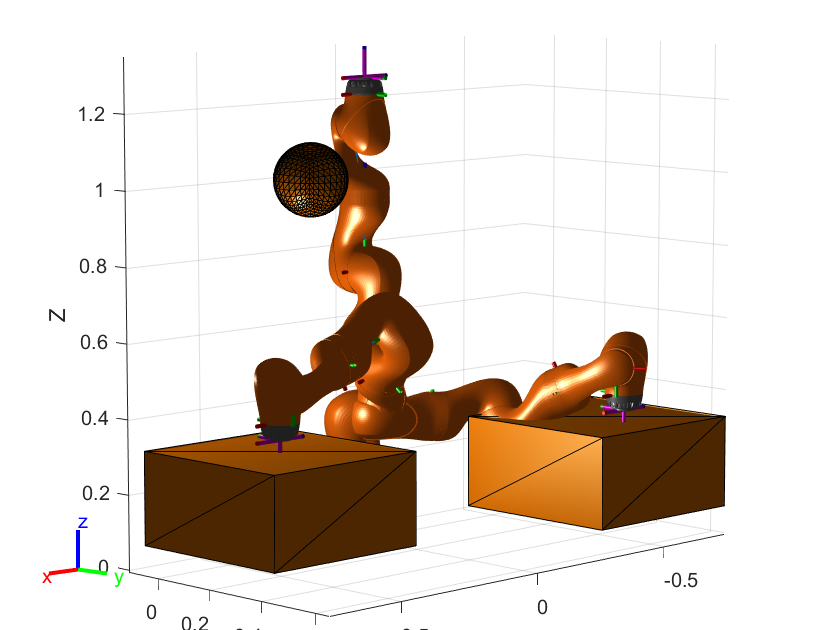


robot = loadrobot("kukaIiwa7","DataFormat","column","Gravity",[0 0 -9.81]);
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
show(robot,homeConfiguration(robot),"Parent",ax);
startPose = trvec2tform([-0.5,0.5,0.4])*axang2tform([1 0 0 pi]);
endPose = trvec2tform([0.5,0.2,0.4])*axang2tform([1 0 0 pi]);
% Use a fixed random seed to ensure repeatable results
rng(0);
ik = inverseKinematics("RigidBodyTree",robot);
weights = ones(1,6);
startConfig = ik("iiwa_link_7",startPose,weights,robot.homeConfiguration);
endConfig = ik("iiwa_link_7",endPose,weights,robot.homeConfiguration);

% Show initial and final positions
show(robot,startConfig);
show(robot,endConfig);


q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],200,"EndTime",2);

% Initialize outputs
inCollision = false(length(q), 1); % Check whether each pose is in collision
worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision

for i = 1:length(q)
    
    [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
    
    [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
    worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
    worldCollisionPairIdx{i} = worldCollidingPairs;
    
end
  
isTrajectoryInCollision = any(inCollision)

isTrajectoryInCollision = logical
   1


collidingIdx1 = find(inCollision,1);
collidingIdx2 = find(inCollision,1,"last");

% Identify the colliding rigid bodies.
collidingBodies1 = worldCollisionPairIdx{collidingIdx1}*[1 0]';
collidingBodies2 = worldCollisionPairIdx{collidingIdx2}*[1 0]';

% Visualize the environment.
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);


% Add the robots & highlight the problem bodies
show(robot,q(:,problemIdx1),"Parent",ax,"PreservePlot",false);

Unrecognized function or variable 'problemIdx1'.

exampleHelperHighlightCollisionBodies(robot,problemBodies1,ax);
show(robot,q(:,problemIdx2),"Parent"',ax);
exampleHelperHighlightCollisionBodies(robot,problemBodies2,ax);

intermediatePose1 = trvec2tform([-.3 -.2 .6])*axang2tform([0 1 0 -pi/4]); % Out and around the sphere
intermediatePose2 = trvec2tform([0.2,0.2,0.6])*axang2tform([1 0 0 pi]); % Come in from above

intermediateConfig1 = ik("iiwa_link_7",intermediatePose1,weights,q(:,problemIdx1));
intermediateConfig2 = ik("iiwa_link_7",intermediatePose2,weights,q(:,problemIdx2));

% Show the new intermediate poses
ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);
show(robot,intermediateConfig1,"Parent",ax,"PreservePlot",false);
show(robot,intermediateConfig2,"Parent",ax);
[q,qd,qdd,t] = trapveltraj([homeConfiguration(robot),intermediateConfig1,startConfig,intermediateConfig2,endConfig],200,"EndTime",2);

%Initialize outputs
isCollision = false(length(q),1); % Check whether each pose is in collision
collisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
for i = 1:length(q)
    [isCollision(i),collisionPairIdx{i}] = exampleHelperManipCheckCollisions(robot,collisionArray,worldCollisionArray,q(:,i),false);
end
isTrajectoryInCollision = any(isCollision)